## S18C Barcode Detection Documentation

Jean-Nicola Blanchet, August 2020

The purpose of this document is to explain each step of the proposed solution to the barcode detection problem, as well as the parsing and decoding process. Detection is a computer vision problem defined as the search of the location of an object of a specific class in an image. In this instance, the class of the object of interest is a S18C barcode.

Tools for unit testing and benchmarking are made available in our GitHub repository.

### Loading the a sample Image from the synthetic dataset

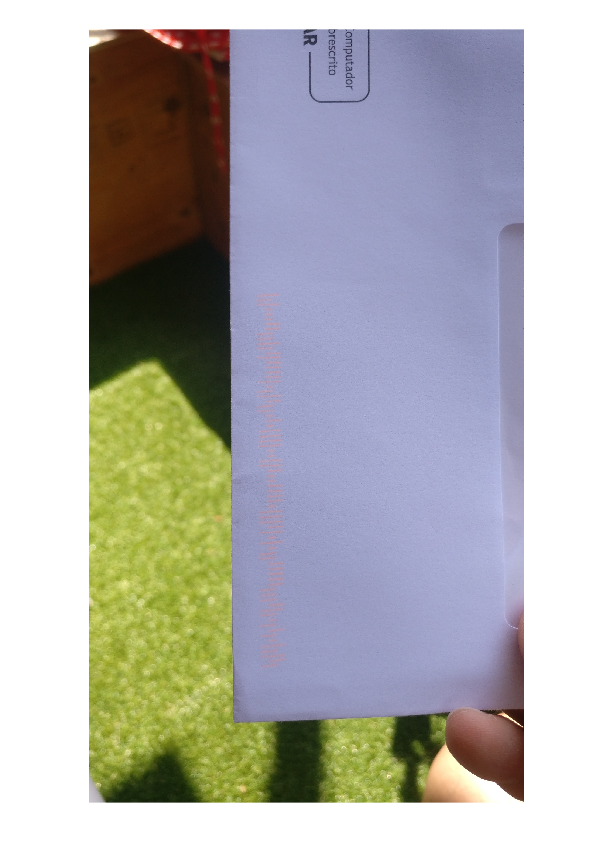

clear
clc
close all

f = im2double(imread('../data/real/IMG_20200813_120837.jpg'));
figure, imshow(f)

### Preprocessing

The image is resized to a third of its original size (strictly for performance) using nearest neighbor interpolation (or subsampling).

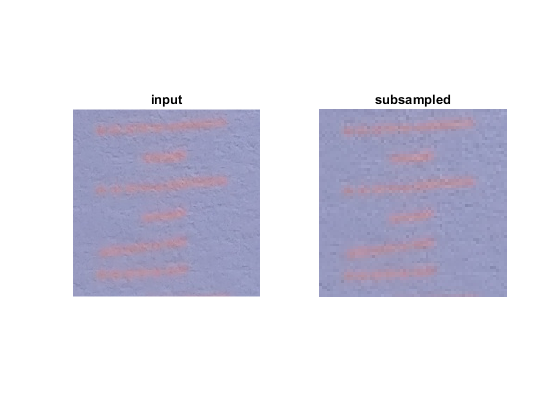

%% Feature Extraction
SCALE_FACT = 3;

f_small = imresize(f,1/SCALE_FACT,'nearest');

figure
subplot(1,2,1), imshow(f(3000:3200,1000:1200,:)), title('input')
subplot(1,2,2), imshow(f(3000:3:3200,1000:3:1200,:)), title('subsampled')

### Feature Extraction

The image is divided in cells, and each cell is described by a color feature. This feature is a novel type of phase histogram, which we call Color Phase Histogram. This feature is robust to global change in the image (e.g. different white balance settings, different exposures, different lighting conditions, different tone mapping and color balance, etc) , and is extracted as follow:

- The derivative of the image is approximated with a pair of Sobel filters. on each image channel.

- Phase information is extracted. While we aim to extract mostly color phase information, spatial phase information is also useful due to the distinctiveness of the bar code pattern. Intuitively, pixels will exhibit both change patterns: from white to orange, and from orange to white. To keep some spatial information, the color phase is extracted in RGB space for each component of the gradient (x and y), and combined at the next step thus preserving the sign. Because the color phase is 3 dimensional (RGB), two angles are needed to describe the gradient's phase: $\mathrm{atan2}\left(G,R\right),\;\mathrm{atan}\left(\frac{B}{\left|\right|R+B\left|\right|}\right)$ where red, green and blue are the components of the gradient vector.

- The angles are binned and aggregated into a histogram. We found that some bins are extremely rare in practice, so we discard them. from the feature vector.

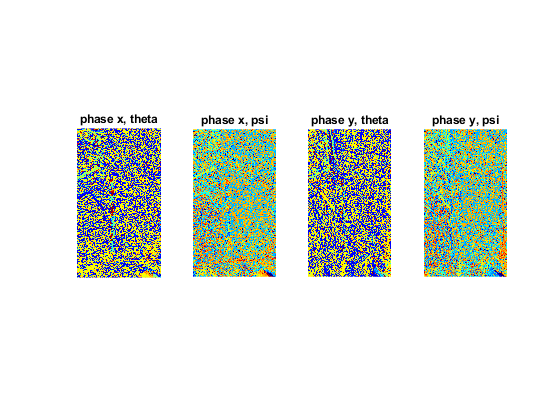

gx_buff = zeros(size(f_small),class(f_small));
gy_buff = zeros(size(f_small),class(f_small));
for channel=1:3
    gx_buff(:,:,channel) = conv2(f_small(:,:,channel),[-1 -2 -1; 0 0 0; 1 2 1],'same');
    gy_buff(:,:,channel) = conv2(f_small(:,:,channel),[-1 0 1; -2 0 2; -1 0 1],'same');
end

colorphase = cat(3,...
    atan2(gx_buff(:,:,2),gx_buff(:,:,1)),...
    atan(gx_buff(:,:,3)./(sqrt(gx_buff(:,:,1).^2+gx_buff(:,:,2).^2))),...
    atan2(gy_buff(:,:,2),gy_buff(:,:,1)),...
    atan(gy_buff(:,:,3)./(sqrt(gy_buff(:,:,1).^2+gy_buff(:,:,2).^2)))...
    );

figure
subplot(1,4,1), imshow(colorphase(:,:,1),[]), title('phase x, theta'), colormap('jet')
subplot(1,4,2), imshow(colorphase(:,:,2),[]), title('phase x, psi'), colormap('jet')
subplot(1,4,3), imshow(colorphase(:,:,3),[]), title('phase y, theta'), colormap('jet')
subplot(1,4,4), imshow(colorphase(:,:,4),[]), title('phase y, psi'), colormap('jet')

For the histogram accumulation, the image is divided into cells of 5x5 pixels, and a histogram of 25 values is computed.

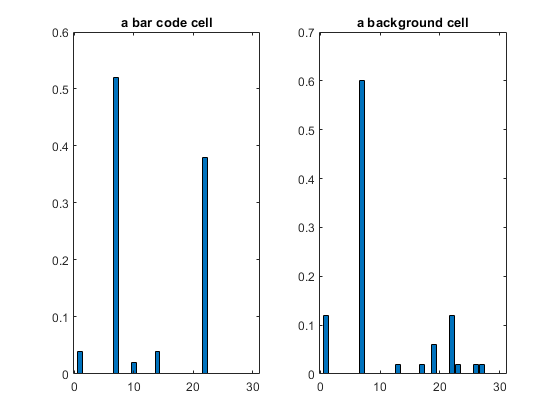

% accumulate feature hitogram (in a compilation friendly way)
BLOCK_SIZE = 5;
N_BINS_P1 = 6;
N_BINS_P2 = 6;
N_BINS = N_BINS_P1 * N_BINS_P2;
grid_x = floor(size(f_small,1) / BLOCK_SIZE);
grid_y = floor(size(f_small,2) / BLOCK_SIZE);
features = zeros(grid_x,grid_y,N_BINS,'single');
for cell_x = 0:grid_x-1
    for cell_y = 0:grid_y-1
        for px_x = cell_x * BLOCK_SIZE:(cell_x+1) * BLOCK_SIZE - 1
            for px_y = cell_y * BLOCK_SIZE:(cell_y+1) * BLOCK_SIZE - 1
                % gx
                b1 = floor((pi + colorphase(px_x+1,px_y+1,1)) ./ (2*pi) * (N_BINS_P1-1));
                b2 = floor((pi/2 + colorphase(px_x+1,px_y+1,2)) ./ (pi) * (N_BINS_P2-1));
                b = b1 + b2 * N_BINS_P1;
                if b >= 0 && b < N_BINS
                    features(cell_x+1,cell_y+1,b+1) = features(cell_x+1,cell_y+1,b+1) + 1;
                end
                % repeat for gy
                b1 = floor((pi + colorphase(px_x+1,px_y+1,3)) ./ (2*pi) * (N_BINS_P1-1));
                b2 = floor((pi/2 + colorphase(px_x+1,px_y+1,4)) ./ (pi) * (N_BINS_P2-1));
                b = b1 + b2 * N_BINS_P1;
                if b >= 0 && b < N_BINS
                    features(cell_x+1,cell_y+1,b+1) = features(cell_x+1,cell_y+1,b+1) + 1;
                end
            end
        end
    end
end

% normalize
maxbin = 30;
features = features(:,:,1:maxbin);
features = features / (2*BLOCK_SIZE*BLOCK_SIZE);
features = reshape(features,size(features,1)*size(features,2),size(features,3));

figure
subplot(1,2,1), bar(features(310*128+74,:)), title('a bar code cell')
subplot(1,2,2), bar(features(500,:)), title('a background cell')

### Classification

Cells are classified into one of two classes: barcode (1) vs background (0) using a single dot product, followed by a threshold. The weight vector was obtained using linear regression on training data. The threshold is adaptive: we select the 98th percentile value. The rationale is that the top 2% cells are likely to be condensed around the barcode area, if such a code is present in the image.

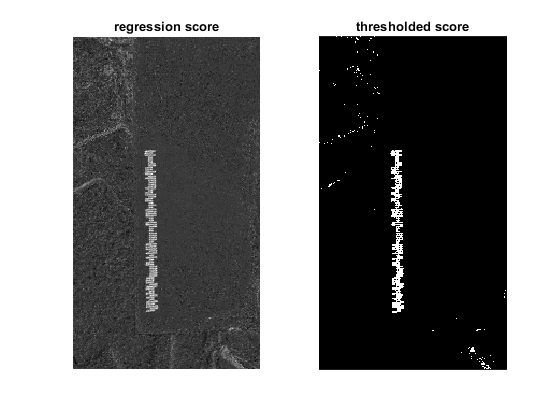


%% Classify
% Weight matrix M is from linear regression on a training set of images that was manually labeled.
% To perform linear regression simply use M = feature \ label; where label is a binary vector.
M = [    0.0527    1.5903    0.9982   -0.0369   -0.5392   -0.1954    0.1030    0.7808    2.9037   -0.8245   -1.3336   -1.5216    0.7569   -1.2331    0.1142   -0.4805    0.7901   -1.8255    1.6295   -2.3931   -0.4514   -0.0468   2.2480    0.8620   -1.4884   -1.3545   -0.4550   -0.5069    3.8599   -1.3284]';
score = features * M; % eval
score = reshape(score,grid_x,grid_y);
score = (score - min(score(:))) / (max(score(:)) - min(score(:)));
valid = score > prctile(score(:),98);

figure
subplot(1,2,1), imshow(score), title('regression score')
subplot(1,2,2), imshow(valid), title('thresholded score')

### Classification post-processing

A quick dilation is applied to connect nearby cells.

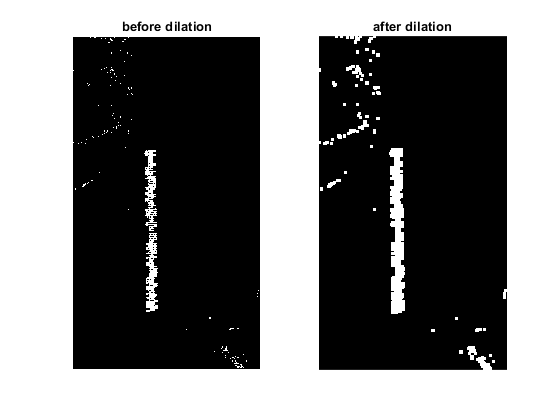

valid_ = reshape(valid,grid_x,grid_y);
% left
for x = 1:grid_x
    for y = 2:grid_y
        if valid_(x,y)
            valid_(x,y-1) = true;
        end
    end
end
% right
for x = 1:grid_x
    for y = grid_y-1:-1:1
        if valid_(x,y)
            valid_(x,y+1) = true;
        end
    end
end
% top
for x = 2:grid_x
    for y = 1:grid_y
        if valid_(x,y)
            valid_(x-1,y) = true;
        end
    end
end
% bottom
for x = grid_x-1:-1:1
    for y = 1:grid_y
        if valid_(x,y)
            valid_(x+1,y) = true;
        end
    end
end

figure
subplot(1,2,1), imshow(valid), title('before dilation')
subplot(1,2,2), imshow(valid_), title('after dilation')

The largest candidate is identified

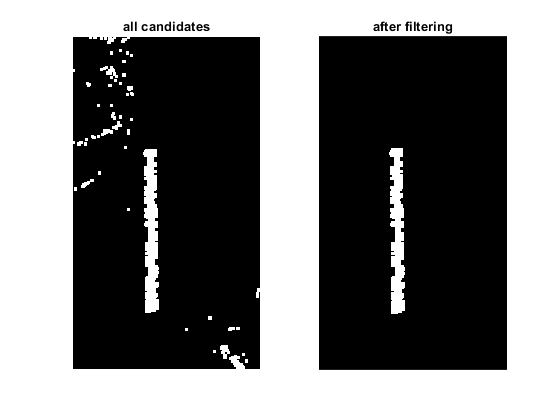

[CC,n] = bwlabel(valid_);

best_bar_code = false(size(CC));
if n == 0
    % no valid regions were identified return error
elseif n > 1
    % keep only the largest region<
    barcode_candidate_area = zeros(n,1,'uint32');
    for lbl = 1:numel(CC)
        if CC(lbl) > 0
            barcode_candidate_area(CC(lbl)) = barcode_candidate_area(CC(lbl)) + 1;
        end
    end
    [maxarea,id] = max(barcode_candidate_area);
    
    best_bar_code = CC == id;
else
    best_bar_code = logical(CC);
end

figure()
subplot(1,2,1), imshow(valid_), title('all candidates')
subplot(1,2,2), imshow(best_bar_code), title('after filtering')

Properties of the remaining region are extracted:

The **centroid **will be useful for applying rotation later. The **eccentricity **is used as a sanity check to reject a box could not contain a barcode. The **orientation** is used to correctly extract the barcode. and the **bounding box** is used for user feedback.

scale = size(f,1) / size(valid_,1);
[idx,idy] = ind2sub(size(best_bar_code),find(best_bar_code));

centroid = [mean(idx) mean(idy)];
x0 = (min(idx)-1);
x1 = (max(idx));
y0 = (min(idy)-1);
y1 = (max(idy));
boundingbox = (single([y0 x0 y1 x1] * scale));

pts = double([idx(:), idy(:)]) - repmat(double(centroid),numel(idx),1); % matrix operation broadcast doesn't compile well

[~,S,V] = svd(pts);
D = diag(S);

eccentricity = 1 - (D(2) / D(1)); % how line-like is this shape?
orientation = 90+rad2deg(atan2(V(2),V(1)));

if eccentricity < 0.80
    % it does not look like a bar! the length-width ratio is off
    error('not a barcode!')
end

rot = @(angle) [cosd(angle), -sind(angle); sind(angle), cosd(angle)];
rotated_bb = (rot(-orientation) * (pts)' + repmat(centroid',1,size(pts,1)));
W = ceil(max(rotated_bb(2,:)) - min(rotated_bb(2,:))) + 5; % extra padding to capture all the edges
H = ceil(max(rotated_bb(1,:)) - min(rotated_bb(1,:)));


### Barcode extraction and rendering

Using the centroid and orientation, we can extract a large patch of 800 pixels where the barcode was found. We compute a pixel-wise "orangeness" measurement that contrast well with the enveloppe (2R - G - B), and normalize to identify the most orange pixels in the image patch.

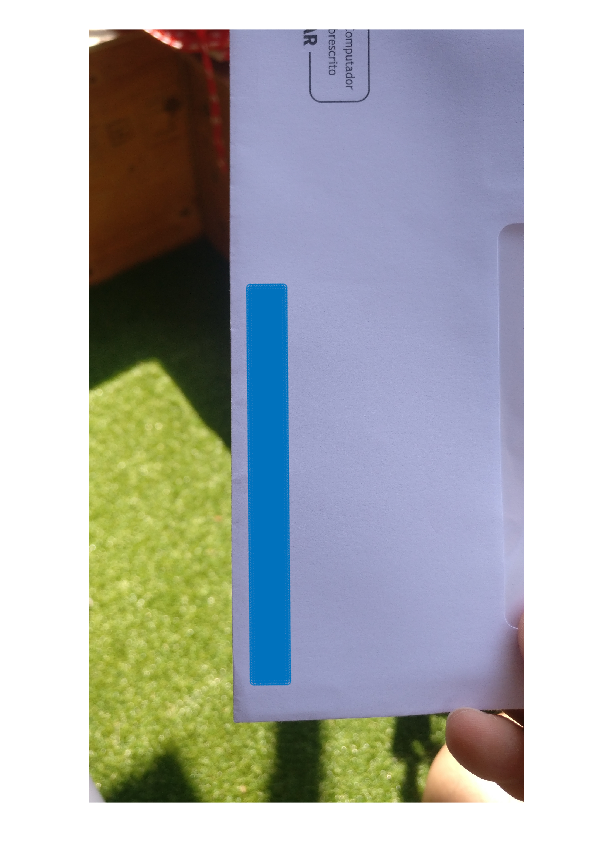


%% Extract barcode ROI
% extract high resolution region of interest with bilinear interpolation
scale = size(f,1) / size(best_bar_code,1);

[yy,xx] = meshgrid(-W/2:W/2-1, -H/2:H/2-1);
pts = scale * (rot(orientation) * [xx(:),yy(:)]' + repmat((centroid-1)',1,numel(xx)));

figure, imshow(f)
hold on
scatter(pts(2,:),pts(1,:))
hold off

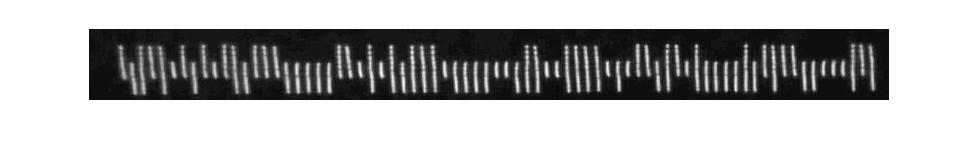


TARGET_WIDTH = 800;
xx = imresize(reshape(pts(1,:),[H,W]),TARGET_WIDTH / W);
yy = imresize(reshape(pts(2,:),[H,W]),TARGET_WIDTH / W);

imbar = applyLookUpTable(f,xx,yy);

red_ratio = @(im) (2*im(:,:,1)) - (im(:,:,2) + im(:,:,3));
imbar_score = red_ratio(imbar);
minscore = min(imbar_score(:));
maxscore = max(imbar_score(:));
imbar_score = (imbar_score - minscore) / (maxscore - minscore);

figure
imshow(imbar_score)

The bar code region is then refined by looking at column-wise sum and row-wise sum.

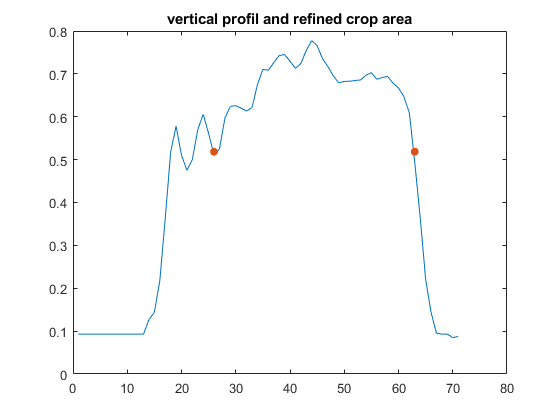

[H,W] = size(imbar_score);
% find the top and the bottom
vertical_profile = prctile(imbar_score,90,2);
T = max(vertical_profile)/1.5;
span = [1 1];
for i=round(H/2):-1:1 % find upper bound
    if vertical_profile(i) < T
        span(1) = i;
        break;
    end
end
for i=round(H/2):1:H % find lower bound
    if vertical_profile(i) < T
        span(2) = i;
        break;
    end
end
imbar_score = imbar_score(span(1):span(2),:);
figure
plot(vertical_profile)
hold on
scatter(span,[T T],'filled')
hold off
title('vertical profil and refined crop area')

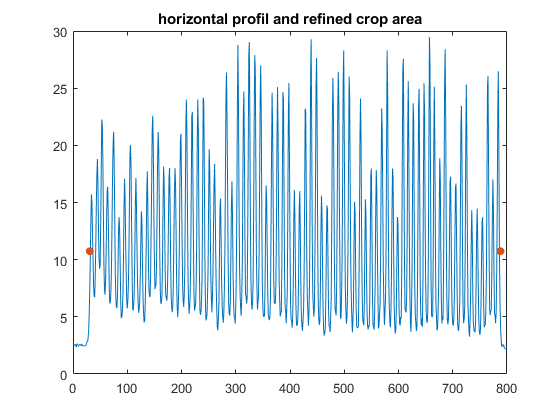



horizontal_profile = sum(imbar_score,1);
T = mean(horizontal_profile);
peaks = find(horizontal_profile > T);
span = [max(1,peaks(1)-2) min(W,peaks(end)+2)];
imbar_score = imbar_score(:,span(1):span(2));

figure
plot(horizontal_profile)
hold on
scatter(span,[T T],'filled')
hold off
title('horizontal profil and refined crop area')

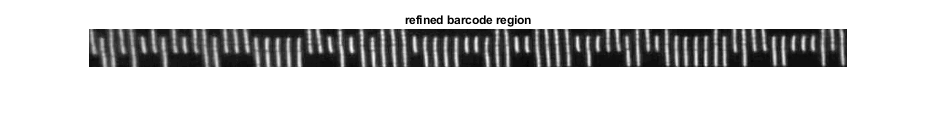


figure,
imshow(imbar_score,[])
title('refined barcode region')

### Barcode signal processing

The final barcode is processed to enhance binary information.

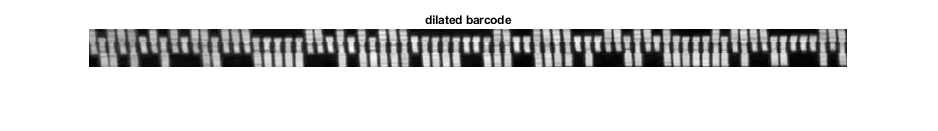

[H,W] = size(imbar_score);
t0 = round(H/3);
t1 = round(2*H/3);

% dilate (top and bottom have more weight
imbar_score_dilate = zeros(size(imbar_score));
for i = 1:size(imbar_score_dilate,1)
    w = 1;
    if i <= t0 || i >= t1
        w = 2;
    end
    for j = 1:size(imbar_score_dilate,2)
        imbar_score_dilate(i,j) = max(imbar_score(i,max(1,j-w):min(j+w,W)));
    end
end

figure, imshow(imbar_score_dilate,[])
title('dilated barcode')

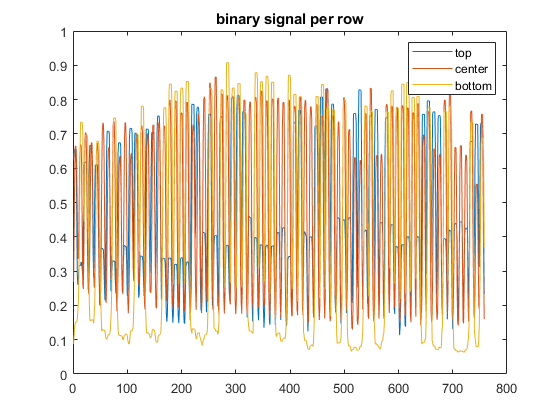


row0_profile = mean(imbar_score_dilate(1:t0,:));
row1_profile_unfiltered = mean(imbar_score_dilate(t0+1:t1,:));
row2_profile = mean(imbar_score_dilate(t1:end,:));

% apply a laplacian filter to enhance peaks. kernel size is based on 800 px divided by 75 bars
% this works well because the center band of the signal is perfectly cyclical
h = 2*[0.4490    0.3747    0.1853   -0.1663   -0.5111   -0.6667   -0.5111   -0.1663    0.1853    0.3747    0.4490 ];
lap = conv([ones(1,5) * row1_profile_unfiltered(1), row1_profile_unfiltered, ones(1,5) * row1_profile_unfiltered(end)],h,'valid');
row1_profile = row1_profile_unfiltered - lap;

figure, plot([row0_profile;row1_profile_unfiltered;row2_profile]'), legend({'top','center','bottom'})
title('binary signal per row')

### Barcode binary parsing and error correction

Using otsu's adaptive threshold method, the center row of the signal is binarized. If 75 peaks are identified, the centroid of each peak is computed.

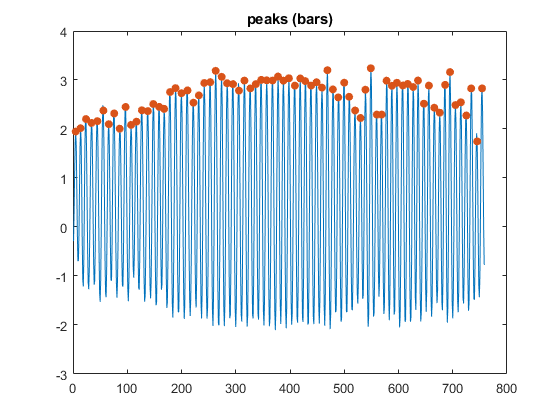

H = hist(row1_profile,0:0.01:1);
threshC = otsuthresh(H);
C = row1_profile > threshC; % center
% we're looking for 75 bars
[cc,n] = bwlabel(C);
if n ~= 75
    error('expected 75 bars!')
end

sampling_centroid = zeros(1,75);
sampling_count = zeros(1,75);
for i=1:numel(cc)
    lbl = cc(i);
    if lbl > 0
        sampling_centroid(lbl) = sampling_centroid(lbl) + i;
        sampling_count(lbl) = sampling_count(lbl) + 1;
    end
end
sampling_centroid = round(sampling_centroid ./ sampling_count);


figure,
plot(row1_profile)
hold on
scatter(sampling_centroid,row1_profile(sampling_centroid),'filled')
hold off
title('peaks (bars)')

Using the center row to calibrate the contextual grayscale, the top and bottom row are binarized.

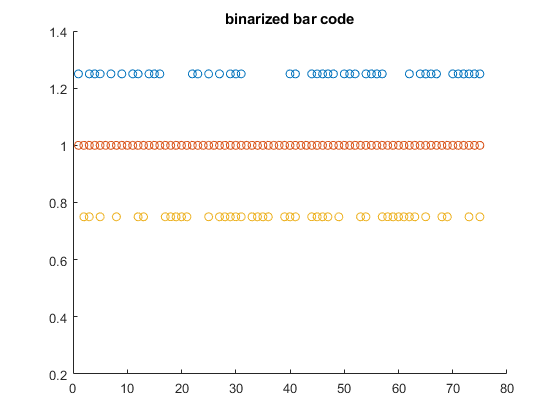

% if 75 good bars were found, we can read the top and bottom row
% which contain the binary signal
T = false(1,75);
B = false(1,75);
for c=1:numel(sampling_centroid)
    peak = sampling_centroid(c);
    if c==1
        bottom = round((sampling_centroid(c) + sampling_centroid(c+1))/2);
    elseif c==numel(sampling_centroid)
        bottom = round((sampling_centroid(c-1) + sampling_centroid(c))/2);
    else
        bottom = [round((sampling_centroid(c-1) + sampling_centroid(c))/2), ...
            round((sampling_centroid(c+1) + sampling_centroid(c))/2)];
    end
    
    expected_white = row1_profile_unfiltered(peak);
    expected_black = min([row1_profile_unfiltered(bottom)]);
    
    % make it true if it's closer to the peak
    T(c) = abs(row0_profile(peak) - expected_white) < abs(row0_profile(peak) - expected_black);
    B(c) = abs(row2_profile(peak) - expected_white) < abs(row2_profile(peak) - expected_black);
end

figure
scatter(1:75,T*1.25);
hold on
scatter(1:75,C(sampling_centroid)*1);
scatter(1:75,B*0.75);
hold off
title('binarized bar code');
ylim([0.2 1.4])

### Barcode parsing and error correction

Using the official normative definition directly from the S18d document on the topic of the 75-bar S18C barcode format, we parse the binary data into a valid ID-Tag. Solomon Reed error correction is applied to ensure quality.

%% Identify code orientation
% we're are allowing 1 error to occur in the sync codes, as it will be
% corrected later with the solomon reed error correction method.

% top,bottom bits values: 00, 01, 10, 11 where 1 is white
codes = ['T','D','A','F'];
code_ = codes(1+T * 2 + B);
% check orientation
left_sync = code_(7:9);
right_sync = code_(numel(code_)-8:numel(code_)-6);
isvalid = true;
if sum('AADDAD' == [left_sync right_sync]) < 5 % 1 character can be wrong
    % if the sync codes are wrong, the code may be flipped
    codes = ['T','A','D','F'];
    code_ = codes(1+T(end:-1:1) * 2 + B(end:-1:1));
    left_sync = code_(7:9);
    right_sync = code_(numel(code_)-8:numel(code_)-6);
    if sum('AADDAD' == [left_sync right_sync]) < 5
        % error: code was misread because the sync codes are wrong
        isvalid = false;
    end
end
% we tolerate 1 wrong bar, so we'll fix it
code_(7:9) = 'AAD';
code_(numel(code_)-8:numel(code_)-6) = 'DAD';

if ~isvalid
    exitcode = int32(-4);
    return;
end

%% Apply solomon reed error correction
% convert to decimal
fullBinary = true(2,75);
for i=1:numel(code_)
    if code_(i) == 'F'
        fullBinary(:,i) = [false; false];
    elseif code_(i) == 'A'
        fullBinary(:,i) = [false; true];
    elseif code_(i) == 'D'
        fullBinary(:,i) = [true; false];
    end
end
fullBinary = fullBinary(:)';
decimal = sum(reshape(fullBinary,6,[])' .* repmat([32 16 8 4 2 1],25,1),2)';

% apply correction
[corrected, ecc] = solomonreed(decimal);
code_dec = [corrected(1:10) ecc corrected(11:13)];


% convert back to code words
LUT =  ['FFF'; 'FFA'; 'FFD'; 'FFT'; 'FAF'; 'FAA'; 'FAD'; 'FAT';
    'FDF'; 'FDA'; 'FDD'; 'FDT'; 'FTF'; 'FTA'; 'FTD'; 'FTT';
    'AFF'; 'AFA'; 'AFD'; 'AFT'; 'AAF'; 'AAA'; 'AAD'; 'AAT';
    'ADF'; 'ADA'; 'ADD'; 'ADT'; 'ATF'; 'ATA'; 'ATD'; 'ATT';
    'DFF'; 'DFA'; 'DFD'; 'DFT'; 'DAF'; 'DAA'; 'DAD'; 'DAT';
    'DDF'; 'DDA'; 'DDD'; 'DDT'; 'DTF'; 'DTA'; 'DTD'; 'DTT';
    'TFF'; 'TFA'; 'TFD'; 'TFT'; 'TAF'; 'TAA'; 'TAD'; 'TAT';
    'TDF'; 'TDA'; 'TDD'; 'TDT'; 'TTF'; 'TTA'; 'TTD'; 'TTT'];
code_(:) = LUT(code_dec+1,:)';

% crop out sync codes, copy the rest to a new buffer
valid = true(1,numel(code_));
valid([7:9 numel(code_)-8:numel(code_)-6]) = false;
code = code_(valid);
buscode = code_; % copy the bus code to the returned buffer

assert(all( size(code) == [1 69]));

% convert to binary
binary = true(2,69);
for i=1:numel(code)
    if code(i) == 'F'
        binary(:,i) = [false; false];
    elseif code(i) == 'A'
        binary(:,i) = [false; true];
    elseif code(i) == 'D'
        binary(:,i) = [true; false];
    end
end
binary = binary(:)';

assert(all( size(binary) == [1 138]));

% +1 for MATLAB 1 based indexing
parsebin2dec = @(bin) bin2dec(char(uint8(bin)+48));

%% field 1: UPU identifier
UPU_identifier = 'J'; % always J

s18ccode(1) = UPU_identifier;

disp(sprintf('UPU_identifier is always J: %c',char(UPU_identifier)));

UPU_identifier is always J: J



%% field 2: format
% TODO: error detection, only [1 4] possible
format_identifier_bits = (0:3)+1;
format_identifier_id = parsebin2dec(binary(format_identifier_bits));
if format_identifier_id ~= 2
    error('unsupported format')
end

%format_identifiers = {'18A','18B','18C','18D'};
format_identifier = '   ';
if format_identifier_id == 0
    format_identifier = '18A';
elseif format_identifier_id == 1
    format_identifier = '18B';
elseif format_identifier_id == 2
    format_identifier = '18C';
elseif format_identifier_id == 3
    format_identifier = '18D';
end

s18ccode(2:4) = format_identifier;

disp(sprintf('format_identifier is: %s',char(format_identifier)));

format_identifier is: 18C




%% field 3: issuer_code
issuer_code_bits = (4:19)+1;
%3 characters
%1: S18 table 1, INT(I/1600)
%2: INT(MOD(I,1600)/40_ S18a, table 1
%3: MOD(I,40)

alphabet_table1 = 'ZYXWVUTSRQPONMLKJIHGFEDCBA9876543210';
issuer_code_id = parsebin2dec(binary(issuer_code_bits));
% issuer_code_id = 16003;
% issuer_code_id = parsebin2dec([0 0 1 0 0 0 0 0 0 1 1 1 0 0 0 1]);
% pzw
issuer_code_id_1 = floor((issuer_code_id) / 1600);
issuer_code_1 = alphabet_table1(issuer_code_id_1+1);

issuer_code_id_2 = floor(mod((issuer_code_id),1600)/40);
issuer_code_2 = alphabet_table1(issuer_code_id_2+1);

issuer_code_id_3 = floor(mod((issuer_code_id),40));
issuer_code_3 = alphabet_table1(issuer_code_id_3+1);

issuer_code = [issuer_code_1, issuer_code_2, issuer_code_3];

s18ccode(5:7) = issuer_code;

disp(sprintf('issuer_code is: %s',char(issuer_code)));

issuer_code is: PTA



%% field 4: equipement_id
hex_table1 = '0123456789ABCDEF';
equipement_id_bits_1 = (20:23)+1; % hex 0-9;A-F
equipement_id_bits_2 = (24:27)+1;
equipement_id_bits_3 = (28:31)+1;

equipement_id_1 = hex_table1(1+parsebin2dec(binary(equipement_id_bits_1)));
equipement_id_2 = hex_table1(1+parsebin2dec(binary(equipement_id_bits_2)));
equipement_id_3 = hex_table1(1+parsebin2dec(binary(equipement_id_bits_3)));

equipement_id = [equipement_id_1, equipement_id_2, equipement_id_3];

s18ccode(8:10) = equipement_id;
disp(sprintf('equipement_id is: %s',char(equipement_id)));

equipement_id is: 154




%% field 5: item_priority
item_priority_bits = (32:33)+1; % hex 0-9;A-F

priorities = ['N','L','H','U']; % from 0 to 3
item_priority = priorities(1+parsebin2dec(binary(item_priority_bits)));

s18ccode(11) = item_priority;

disp(sprintf('item_priority is: %s',char(item_priority)));

item_priority is: U




%% field 6: serial_number
serial_number_bits = (34:49)+1;
%3 characters
%1: floor(D/5120) + 1
%2: floor(mod(D,5120)/160)
%3: floor(mod(D,160)/6)
%4: mod(mod(D,160),6)
serial_number = (parsebin2dec(binary(serial_number_bits)));
serial_number_month = int32(floor(serial_number/5120) + 1);
serial_number_day = int32(floor(mod(serial_number,5120)/160));
serial_number_hour = int32(floor(mod(serial_number,160)/6));
serial_number_10min = int32(mod(mod(serial_number,160),6));

serial_number_formatted = sprintf('%02d%02d%02d%d',serial_number_month,serial_number_day,serial_number_hour,serial_number_10min);
assert(all( size(serial_number_formatted) == [ 1, 7 ]))

s18ccode(12:18) = serial_number_formatted;

disp(sprintf('serial_number is: %02d%02d%02d%d',serial_number_month,serial_number_day,serial_number_hour,serial_number_10min));

serial_number is: 0723143




%% field 7 (note: 18D not implemented)
n = numel(binary)-1;
serial_number_item_bits = ([(n-9):n])+1;
serial_number_item = int32(parsebin2dec([binary(serial_number_item_bits)]));
serial_number_item_formatted = sprintf('%05d',serial_number_item);
assert(all( size(serial_number_item_formatted) == [ 1, 5 ]))

s18ccode(19:23) = serial_number_item_formatted;

disp(sprintf('serial_number_item is: %s',serial_number_item_formatted));

serial_number_item is: 00134




%% field 8
tracking_indicator_bits = ([(n-11):(n-10)])+1; % hex 0-9;A-F

tracking = ['T','F','D','N']; % from 0 to 3
tracking_indicator = tracking(1+parsebin2dec(binary(tracking_indicator_bits)));

s18ccode(24) = tracking_indicator;

disp(sprintf('tracking is: %c',tracking_indicator));

tracking is: N





disp(sprintf('final code is: %s',s18ccode));

final code is: J18CPTA154U072314300134N
